# Composition of Transformations

One can perform a composition of two (or more) transformations by multiplying by the corresponding matrices in the appropriate order.

# Example 5

We can see the effect of first rotation the square 30 degrees counterclockwise and then applying the shear from EXAMPLE 3, by plotting the product T*Q*S. Note the order of the matrices; here we first apply the rotation ( Q is the matrix that multiplies S first) and then we apply the shear. 

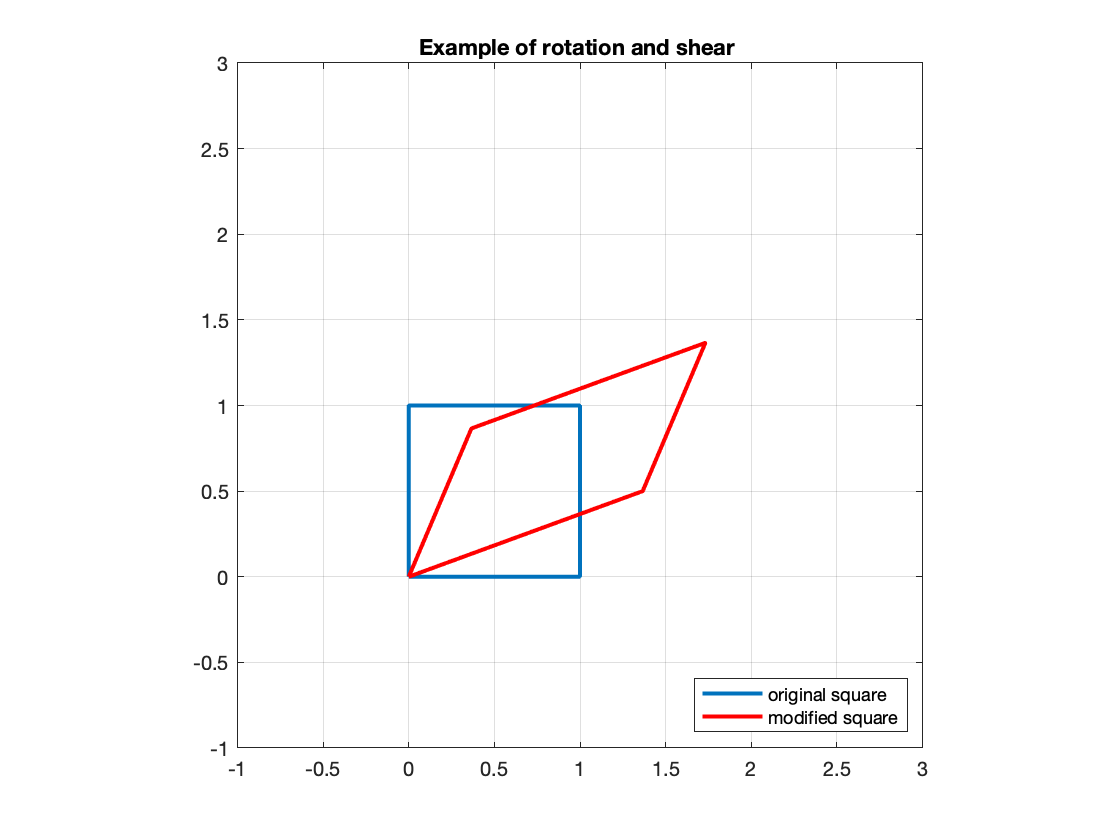

clf
S=[0,1,1,0,0;0,0,1,1,0];
plot(S(1,:),S(2,:),'linewidth',2)
hold on
theta =pi/6; % define the angle
Q=[cos(theta),-sin(theta); sin(theta),cos(theta)];
T =[1,1;0 ,1]; % shear transformation matrix
TQS=T*Q*S;
plot(TQS(1,:),TQS(2,:),'-r','linewidth',2);
title('Example of rotation and shear ')
legend('original square','modified square','location','southeast')
axis equal, 
axis([-1,3,-1,3]); grid on % adjust the axis and the window
hold off